# Exercise 1: Social Behavior

## Goal:  The goal of this exercise is to quantify electrosensory behaviors in restrained fish

Before you start, we will demonstrate how to handle the fish and record their electric fields. We will also demonstrate AMs and Envelopes. Do not let us move forward unless you feel comfortable with those terms/concepts. 

# Experiment

### 1) Place the fish in a **“chirp chamber”** – a tube that reduces the movement of the fish with respect to the recording electrodes. 

### 2) The electrodes located at the front and back are used to record the animal’s EOD, while the electrodes located on the sides are used to deliver electrosensory stimuli. 

### 3) You will use a sinewave generator to produce sinewaves, which gives you control over the *amplitude* and *frequency* of the stimulus. In other experiments you will use a combination of the sinewave generator and Spike2 to produce AM stimuli.

### 4) The stimulus is delivered by an analogue Stimulus Isolation Unit (SIU). 

## Recordings using Spike2

Run Spike2, “**File -> New**”, select data document, and press **Start**. 

Look at Channel 2: it should report  the animal’s EOD frequency. Record it for 2 minutes, then press “**Stop**” to stop recording. 

Don’t forget to save your data: “**File -> Save**.” 

Set up a convention for saving your data. I personally use the following: create a directory in “c:\data\” that has today’s date in numbers. Thus, today’s June 17th 2019, so the directory could be called “061719”. You then can number the files starting from “01.” Your first data file then could be “061719_01.smr”, your second data file “061719_02.smr”, etc…

You’ll find that Spike2 and the data acquisition board have been setup with the following: **Channels 1, 3 and 5** are analog signals that are sampled at a finite rate (**20 kHz for channels 1 and 5, 2 kHz for channel 3)** while **channel 2 **is an event channel that records the times at which the EOD waveform crosses zero from below. These are useful for determining the instantaneous EOD frequency. **Channel 31** contains the time stamps for the onset of single events (i.e., stimuli). 

###                 • **Channel 1:** EOD waveform 

###                 • **Channel 2:** EOD zero-crossings 

###                 • **Channel 3:** AM or other stimulus 

###                 • **Channel 5:** membrane potential *[not used in this experiment]*

###                 • **Channel 31:** marker channel 

## "Beat" stimuli

*Beat stimuli are produced as the sum of two sinewaves. Beat signals are characterized by both AMs and FMs that occur at a rate equal to the difference in frequency (dF) between the two sinewaves.*

The frequency of a beat will always be expressed relative to the fish’s own EOD frequency. This is the 'difference Frequency' (**dF**). When you add two sinewaves that have similar frequencies, they generate AMs and FMs as the two singals go in and out of phase.

For example, a beat of 4 Hz means that you’ll be giving a sinewave whose frequency is 4 Hz above the fish’s EOD frequency while a beat of -4 Hz means that you’ll be giving a sinewave whose frequency is 4 Hz below the fish’s own EOD frequency. 

Let’s start by giving a -1 Hz beat. Start a new data recording and turn on stimulation after ~15 sec. 

    Are there changes in the fish’s EOD frequency? (Depends on species)

    Are there brief (~50 msec duration) changes in EOD frequency? (Again, depends on species.

Turn off stimulation after about 45 sec, what happens to the fish’s EOD frequency after the stimulus is removed? Wait about 1 min before giving another stimulus. 

Try giving dF of -2 Hz, -4 Hz, -8 Hz, -16 Hz, -32 Hz, -64 Hz. 

Also try giving beats of 1, 2, 4, 8, 16, 32, 64 Hz. 

Make sure that you remember which beat is which in your Spike2 files (you can type keystrokes [single letters] to mark the recording). You’ll need to do that for analysis later. 

## Amplitude modulations (AMs)

*AM stimuli are produced by multiplying two sinewaves. AM signals do not have FMs.*

Set the sinewave generator to “external trigger” mode, set the frequency to be slightly higher (+30 Hz or so) than the fish’s EOD frequency. This will produce a sinewave that matches the fish's own EOD - it is this signal that we will multiply with another signal to generate AMs. 

Spike2 will be used to generate the "AMs signals." 

Try giving AMs of 1, 2, 4, 8, 16, 32, 64 Hz. How did the fish react? 

Try further increasing the stimulus intensity (you can do so by increasing the amplitude of the sinewave that is outputted by the sinewave generator). What happens at very high intensities? 

## Envelopes

Envelopes here refer to modulations of AMs over time. In more common joargon, these would be 'envelopes of envelopes' in that AMs are often described as envelopes. Jargon aside, we can easily generate these signals by careful design of our AM stimulus. For example, we can multiple a 20 Hz AM stimulus by a sinewave at 2 Hz. We get two simultaneous signals - an ongoing 20 Hz AM and a 2 Hz envelope.

Do weakly electric fish respond to AMs whose amplitude is also modulated (i.e., envelopes)? 

Try giving a few stimuli in which the amplitude of the AM varies (mimicking movement between the two fish). Does the EOD frequency change? How? 

# Data Analysis

This live editor is set up to take you through the analysis in sections. You can run individual sections by placing the cursor in the section and clicking *Run Section *in the LIVE EDITOR tab or by using the keyboard shortcut (⌘⏎ ).

## Pre-analysis

#### Export files to MatLab

In order to open the data gathered in Spike2, you first have to export the Spike2 files to the MatLab format “***.mat****”*.

- Open the file in Spike2, then click on *file – save as* and name the file accordingly. Then chose “***.mat****”* from the file type menu and click *save*.

- In the next window, make sure that we add all channels and export them - don't forget the time vector for the stimulus channel!

- In the following window, uncheck “**use source name in MatLab variable names**” and select **“Waveform and times”** under layout options. 

- Make sure the new file is either saved in your current MatLab folder or make note of the full file path. Using the addpath command in the command window will tell MatLab where to look for your data. 

#### Load data 

At this stage, you should be able to extract your channel data using the **load_data function. **This function opens your ".mat" exported from Spike2 and stores data from each channel into its own vector. In addition to the sampled data, the time vector for the stimulus channel is stored in the variable marker.

% Load and configure channel data
[EOD0Xings, EOD, EOD_dt, time_EOD, AM, AM_dt, time_AM, vm, vm_dt, dipole, dip_dt, marker] = load_data();

#### Plot raw data

The code below should plot all the stimuli you have recorded from the stimulus channel. The start point of each stimulus is marked by a red dot on the plot. If you only have one stimulus, then the plot should contain only one red marker. 

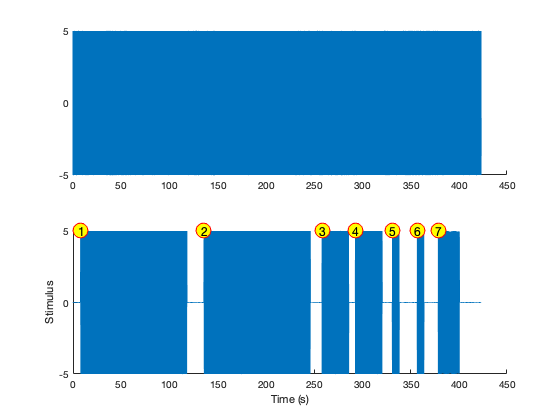


figure(1); clf;

    ax(1) = subplot(211); hold on; 
        plot(time_EOD, EOD) % 
        
    ax(2) = subplot(212); hold on; 
        plot(time_AM, AM) % 

    linkaxes(ax, 'x');
    
% Put red dots at the start point of each stimulus
    for k = 1:length(marker)        
        plot(marker(k), 5, 'or', 'MarkerSize', 15, 'MarkerFaceColor', 'y');
        text(marker(k), 5, num2str(k), 'FontSize', 12, 'HorizontalAlignment', 'center');
    end
    
hold off;
xlabel('Time (s)');
ylabel('Stimulus');

#### Plot EOD frequency response to stimuli

Now let’s filter the EOD Crossings in order to extract the changes in frequency corresponding to the responses to the stimuli you have played. To do this, we will 1) remove stimulus artifacts, and 2) filter noise from the signal.

**1. Remove artifacts**

% find frequencies > 2000 Hz, since these might be artifacts (Double
% triggers, for example)
    badIDXs = find(diff(EOD0Xings) < 1 / (1/AM_dt)); %
    EOD0Xings = EOD0Xings(setdiff(1:length(EOD0Xings), badIDXs)); % Includes only good indices

% Calculate the instatenous frequency (1 / time)
    fEOD_all = 1 ./ diff(EOD0Xings);

% The fish generated its own EODs, which have some variation.
% To do analyses, we want to resample with a regular interval. This will allow us, for example,
% to do frequency filtering on the signal.

% Interpolate vector with the new x-axis (time-stim)
    newfEOD_tot = interp1(EOD0Xings(1:end-1), fEOD_all, time_AM, 'linear'); 
 
%deal with interpolation NaN results
    newfEOD_tot = fillmissing(newfEOD_tot, 'movmean', 5); % replaces NaNs with mean value of interpolation

    % Sometimes there are NANs at the end - let's catch those (ARGH!) and
    % just put the mean frequency there
    if sum(isnan(newfEOD_tot)) > 0
        fprintf('We found %i NaNs. \n', sum(isnan(newfEOD_tot)));
        newfEOD_tot(isnan(newfEOD_tot)) = nanmean(newfEOD_tot); % These are only the indicies that are not NaNs
    end
    

**2. Filter signal**

% Filter EOD using 2nd order butterworth filter with cutoff of 5 Hz
    AMFs = 1/AM_dt;
    [B, A] = butter(3, 5 / (AMFs/2), 'low');
    fEODfilt_tot = filtfilt(B, A, newfEOD_tot(notNaNidx));

**3. Plot filtered EOD frequency**

% Plot the filtered EOD
figure(1); clf;

    ax(1) = subplot(211); plot(time_fEOD, fEODfilt_tot);
    title('EOD frequency during stimulation')
    xlabel('Time (s)')
    ylabel('Frequency (Hz)')
    
    ax(2) = subplot(212); hold on;
    plot(time_AM, AM);
% Put red dots at the start point of each stimulus
    for k = 1:length(marker)        
        plot(marker(k), 5, 'or', 'MarkerSize', 15, 'MarkerFaceColor', 'y');
        text(marker(k), 5, num2str(k), 'FontSize', 12, 'HorizontalAlignment', 'center');
    end
    title('AM stimulus')
    xlabel('Time (s)')
    ylabel('AM')
    
    linkaxes(ax,'x');

Does the fish change its EOD frequency once the stimulus is turned on? Just looking at your data, you should see that the fish can change its EOD frequency in response to both beats and AMs and that the amount by which the frequency increases is dependent on both the beat/AM frequency as well as its intensity. Let’s characterize this dependency. 

## Characterize EOD frequency tuning curve to AMs

Now look at the responses to AMs and the Jamming Avoidance Response (JAR). When you play an AM to the fish, the fish should increase its own EOD frequency in order to move away from the mimic fish, which has an EOD frequency very close to it. Hence, this should also change as a function of the AM frequency.

NOTE: While running the code, you sometimes might experience artifacts (i.e., abrupt changes in EOD frequency, false responses, …) that can contaminate the EOD trace. Since these can lead to errors in the analysis, the provided code can select certain parts of the selected stimulus to analyze in order to avoid running into these issues.

**1. Get start and end ports for each stimulus epoch [startp endp]**

THIS IS A MOTHERFUCKING MESS!

REPLACE WITH ZTHRESH FUNCTION - does it matter if its a positive or negative zero crossing?

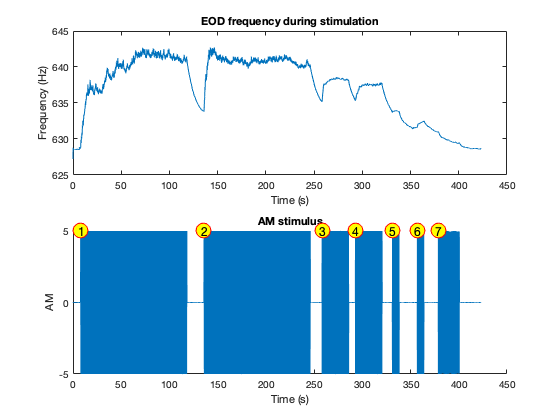

% startp=round(marker*10000);
    AM1 = [AM' -90]';
    AM2 = [-90 AM']';
    indices = find(AM1 >= 1 & AM2 < 1);


%diff = X(2) - X(1)
    diffindices = diff(indices);
    diffindices1 = [diffindices' -90]';
    diffindices2 = [-90 diffindices']';
    cross = find(diffindices1 >= 20000 & diffindices2 < 20000);

    startp = indices(cross+1);
    startp = [indices(1) startp']';
    endp = indices(cross);
    endp = [endp' indices(end)]';

%clear variables so the code can be reused with new data
clear AM1 AM2 indices diffindices diffindices1 diffindices2 cross

**2. Extract EOD frequency excursion for each stimulus**

At this point in the code, you should be able to see that there is an increase in EOD frequency when there is a stimulus playing, and this increase plateaus at a certain point. This is how a JAR looks like. We can extract this JAR by figuring out the difference between the plateau point and the baseline EOD.

Pop-up figures require the user to set thresholds based on a case-by-case basis. Click on the point of the figure where you want to set the threshold.

% for-loop to analyze each stimulus separately
for rot = length(marker):-1:1 %preallocates for speed and mostly just to make matlab happy
    
    freq = input('What is the frequency of the stim?: '); %enter in command window
    AM_freq(rot) = freq; %frequency of fish length of time vector
    
    %stimulus and time within selected indicies for stimulus
    stimulus = AM(startp(rot):endp(rot)); 
    time_stim = time_AM(startp(rot):endp(rot)); 
    
    %baseline EOD frequency
    EODf_baseline = mean(fEODfilt_tot(startp(rot)-(5*(1/AM_dt)):startp(rot)));
    feodtemp = fEODfilt_tot(startp(rot):endp(rot));
    meanEODf = mean(feodtemp);
    
    % detrends the filtered EOD trace in case of any drifting
    feodtemp = detrend(feodtemp,'linear');
    feodtemp = feodtemp+meanEODf;
    %----------------------------------------------------------------------------
    % remove chirps
    figure(001); plot(feodtemp);
    title('threshold the chirps; if no chirps, select below EOD');
    [~, thresh] = ginput(1);
    close 001
    
    newfeodtemp = feodtemp;
    
    if thresh < meanEODf
    else
        [~, loc] = findpeaks(feodtemp, 'MinPeakHeight', thresh);
        durSC = 200;
        
        for I = 1:length(loc)
            
            start = feodtemp(round(loc(I) - durSC));
            endc = feodtemp(round(loc(I) + durSC));
            dur = length((feodtemp(loc(I) - durSC:loc(I) + durSC)));
            extrapoldata = mean([start endc]) * ones(dur, 1);
            newfeodtemp(((loc(I) - durSC:loc(I) + durSC))) = extrapoldata;
            
            clear extrapoldata start endc dur
        end
        
        clear loc
        
    end
    
    clear thresh
    %----------------------------------------------------------------------------
    clf; figure(202); 
    plot(newfeodtemp)
    title('select max EOD frequency');
    baseline_EOD(rot) = EODf_baseline;
    
    % select your plateau EOD where it is maximum
    [~, EOD_max] = ginput(1)
    % calculates your JAR response by subtracting the plateau point from baseline
    JAR(rot) = EOD_max - baseline_EOD(rot);
    
    close 202
    
end

[~, indb] = sort(AM_freq);

**3. Plot the characterization of the AM JAR responses as a function of the AM frequency.**

% x-axis is the AM frequency and y-axis is the JAR
close all; clf; %make sure nothing is already open that may interfere with plotting
figure; 
semilogx(AM_freq(indb), JAR(indb), 'ro-', 'LineWidth', 2);
title('JAR as a function of AM Frequency')
xlabel('AM frequency (Hz)')
ylabel('\Delta EODf (Hz)')

## Characterizing the EOD frequency tuning curve to envelopes

The first part of the following code is identical to the code you used to analyze the JAR. The plot of the filtered EOD should already show the tracking of the envelope stimulus, modulated in the same pattern as what you have played to the fish. Since you can now obtain a gain and phase value for each stimulus, you need to average the behavioral response over the number of cycles in each envelope stimulus. To do this, we first extract the envelope from the stimulus, then find all the peaks in each cycle of the envelope based on the frequency inputted at the beginning of the loop. Next, the we extracts the response from the behavior and generate a peri-stimulus time histogram (PSTH). 

Now that you have both the input (filtered stimulus) and the output (PSTH of behavioral response), you can use this information to perform a sinewave fit in order to calculate the gain and phase and plot them as a function of frequency similar to the JAR..

%% Behavior: ENVELOPE analysis
close all; clf; figure; 
plot(time_AM, AM)
hold on;

    for k = 1:length(marker)
        plot(marker(k), 1 * ones(length(marker(k))), '*r' ,'LineWidth' ,8);
        hold on;
        text(marker(k), 1.1 * ones(length(marker(k))), num2str(k), 'FontSize', 15, 'HorizontalAlignment', 'center');
    end
    
hold off;
xlabel('Time (s)')
ylabel('Stimulus')
%----------------------------------------------------------------------------
% indicate the number of the stimulus to delete; if nothing to delete, hit enter
delete = input('any stimulus to delete?: ');
marker(delete) = [];

% find frequencies > 2000Hz, since these might be artifacts
ind = find(diff(EOD0Xings) < 1/(1/AM_dt));
EOD0Xings = EOD0Xings(setdiff(1:1:length(EOD0Xings), ind));

% eliminate artifacts
fEOD_all = 1./diff(EOD0Xings);

% generate x-axis for the feod vector; note that it has the same length
oldaxis = EOD0Xings(1:end - 1);

% interpolate vector with the new x-axis (time-stim)
newfeod_tot = interp1(oldaxis, fEOD_all, time_AM, 'linear');

%deal with interpolation NaN results
sinds = isnan(newfeod_tot); %NaNs
sinds1 = ~isnan(newfeod_tot); %actual values (not NaNs)
newfeod_tot(sinds) = mean(newfeod_tot(sinds1)); %replaces NaNs with mean value of interpolation

% filter EOD using 2nd order butterworth filter with cutoff 0.01
[B, A] = butter(2, 0.01);
fEODfilt_tot = (filtfilt(B, A, newfeod_tot));

% plot the filtered EOD
close all; clf; figure;
plot(time_AM, fEODfilt_tot);
title('EOD frequency during stimulation')
xlabel('Time (s)')
ylabel('Frequency (Hz)')

%----------------------------------------------------------------------------
% first get the start and endpoints for each stimulus epoch
AM1 = [AM' -90]';
AM2 = [-90 AM']';
indices = find(AM1 >= 1 & AM2 < 1);

diffindices = diff(indices);
diffindices1 = [diffindices' -90]';
diffindices2 = [-90 diffindices']';
cross = find(diffindices1 >= 20000 & diffindices2 < 20000);

startp = indices(cross+1);
startp = [indices(1) startp']';
endp = indices(cross);
endp = [endp' indices(end)]';

clear AM1 AM2 indices diffindices diffindices1 diffindices2 cross


% for-loop to analyze each stimulus separately
for rot = length(marker):-1:1
    
    freq = input('What is the frequency of the stim?: ');
    env_freq(rot) = freq;
    stimulus = AM(startp(rot):endp(rot));
    time_stim = time_AM(startp(rot):endp(rot));
    
    EODf_baseline = mean(fEODfilt_tot(startp(rot)-(5*(1/AM_dt)):startp(rot)));
    feodtemp = fEODfilt_tot(startp(rot):endp(rot));
    meanEODf = mean(feodtemp);
    %----------------------------------------------------------------------------
    % remove chirps
    figure(001); plot(feodtemp);
    title('threshold the chirps; if no chirps, select below EOD')
    [~, thresh] = ginput(1);
    close 001
    
    newfeodtemp = feodtemp;
    
    if thresh < meanEODf
    else
        [~, loc] = findpeaks(feodtemp,'MinPeakHeight',thresh);
        durSC = 200;
        
        for I = 1:length(loc)
            
            start = feodtemp(round(loc(I) - durSC));
            endc = feodtemp(round(loc(I) + durSC));
            dur = length((feodtemp(loc(I) - durSC:loc(I) + durSC)));
            extrapoldata = mean([start endc]) * ones(dur, 1);
            newfeodtemp(((loc(I) - durSC:loc(I) + durSC))) = extrapoldata;
            
            clear extrapoldata start endc dur
        end
        
        clear loc
        
    end
    
    clear thresh feodtemp
    
    % filter EOD using 2nd order butterworth filter with cutoff 0.01
    [B, A] = butter(2,0.001);
    feodtemp = filtfilt(B, A, newfeodtemp);
    
    % detrends the filtered EOD trace in case of any drifting
    feodtemp = detrend(feodtemp, 'linear');
    feodtemp = feodtemp + meanEODf;
    
    close all
    %----------------------------------------------------------------------------
    
    figure(201); plot(feodtemp)
    % choose whether to take entire trace or subsection;
    % this is needed if the response is inconsistent
    choice = menu('Take entire trace?','YES','NO');
    switch choice
        case 1
        case 2
            % define the part you want to analyze using a crosshair
            XPart = ginput(2);
            XPart = round(XPart);
            
            if XPart(1) < 0
                XPart(1) = 1;
            end
            
            if (XPart(2) > length(feodtemp))
                XPart(2) = length(feodtemp);
            end
            
            stimulus = stimulus(XPart(1):XPart(2));
            feodtemp = feodtemp(XPart(1):XPart(2));
            
    end
    
    close 201
    %---------------------------------------------------------------------
    baseline_EOD(rot) = EODf_baseline;
    %---------------------------------------------------------------------
    env = abs(hilbert(stimulus - mean(stimulus)));
    % creates 1st order butterworth filter, change the last value for more or less filtering
    [bb, aa] = butter(1, 0.001);
    env = filtfilt(bb, aa, env);
    env = normalize(env, 'center', 'mean');
    
    envfreq = env_freq(rot);
    fs_stim = 1/AM_dt;
    minpkdist = floor((length(env)/(length(env)/fs_stim * envfreq)) - ...
        (length(env)/(length(env)/fs_stim*envfreq) * 0.1));
    
    if (minpkdist < length(env))
        [dada, peaks] = findpeaks(env, 'minpeakheight', 0, ...
            'minpeakdistance', minpkdist);
    else
        minpkdist = length(env)-1;
        [dada, peaks] = findpeaks(env, 'minpeakheight', 0, ...
            'minpeakdistance',minpkdist);
    end
    
    peaks = peaks(peaks < length(env));
    
    if length(peaks) > 1
        
        if length(peaks) == 2
            maxdiff = max(diff(peaks(1:end)));
        else
            maxdiff = ceil((length(env)/(length(env)/fs_stim * envfreq)));
        end
        
        peaks(1) = peaks(2) - maxdiff;
        
        if peaks(1) < 0
           peaks(1) = 1;
        end
        
        indices3 = find(diff(peaks) < maxdiff/2);
        indices2 = setdiff(1:1:length(peaks), ndices3);
        peaks = peaks(indices2);
        
    end
    
    newpeaks = zeros(length(peaks), 1);
    
    for J = 1:length(newpeaks)
        newpeaks(J) = peaks(1) + (J - 1) * maxdiff;
        
    end
    
    peaks = newpeaks;
    
    clear newpeaks
    %---------------------------------------------------------------------
    psth = zeros(maxdiff, 1);
    
    if envfreq >= 1
        MM = 10;
    else
        MM = 1;
    end
    
    if length(peaks) > 1
        
        for J = 1:length(peaks) - MM
            temp = feodtemp(peaks(J):peaks(J) + maxdiff - 1);
            temp = temp';
            psth = psth + temp;
        end
        
        psth = psth./((length(peaks) - MM));
        
    end
    
    chq1 = diff(psth);
    maxchq1 = max(chq1);
    minchq1 = min(chq1);
    [~, inds_chq1_pos] = min(abs(chq1 - maxchq1));
    [~, inds_chq1_neg] = min(abs(chq1 - minchq1));
    
    if inds_chq1_pos > inds_chq1_neg
        psth(inds_chq1_pos + 1:end, :) = (psth(inds_chq1_pos + 1:end)) - ...
            (abs(chq1(inds_chq1_pos)));
        
    elseif inds_chq1_pos < inds_chq1_neg
        psth(inds_chq1_neg+1:end) = ...
        psth(inds_chq1_neg+1:end) + (abs(chq1(inds_chq1_neg)));
        
    else
    end
    
    clear chq1 inds_chq1_pos chq_inds_neg ff maxchq1 minchq1
    %---------------------------------------------------------------------
    % Nonlinear fitting
    newdt=1/fs_stim;
    
    % the function funENVELOPE generates a sine/cosine wave to fit your PSTH
    % % @(function input values) tells matlab to create a function, this is an alternate method to
    % that described in the tutorial and is for functions you only use in
    % the immediate code
    edges = (1:1:length(psth)) * newdt;
    edges = edges - edges(1);
    funENVELOPE = @(beta0, x) beta0(1) + beta0(2) * cos(2 * pi .* envfreq .* x + beta0(3));
    
    [beta, r, J, Sigma] = nlinfit((1:1:length(psth)) * newdt, psth', funENVELOPE,...
        [mean(psth) (max(psth) - min(psth)/2) 0]);
    yfit = nlpredci(funENVELOPE, (1:1:length(psth)) * newdt, beta, r, 'Covar', Sigma);
    SSE = sum((psth - yfit).^2);
    SST = sum((psth - mean(psth)).^2);
    R = sqrt(1 - SSE/SST)
    
    figure(999);
    plot((1:1:length(psth)) * newdt, psth);
    beta(3) = mod(beta(3), 2*pi);
    
    if beta(2) < 0
       beta(2) = -beta(2);
       beta(3) = beta(3) + pi;
    end
    
    if beta(3) < -pi
       beta(3) = beta(3) + 2*pi;
    end
    
    if beta(3) > pi
        beta(3) = beta(3) - 2*pi;
    end
    
    if beta(3) > 0
        beta(3) = beta(3) - 2*pi;
    end
    
    % by using the command "hold on" the last generated figure will be updated
    % with a second plot
    hold on;
    plot(edges, funENVELOPE(beta, edges), 'r'); 
    pause(1)
    
    close 999
    
    % now calculate gain, phase and offset of the response to envelope stimuli
    gain(rot) = beta(2) * 2/(max(env) - min(env));
    offset(rot) = abs(mean(feodtemp) - EODf_baseline);
    time_estim = (1:1:length(psth)) * fs_stim';
    
    if time_estim(end) >= 1/envfreq - (1/envfreq/10)
        pha = (beta(3)/2/pi*360);
        
        if pha<-300
            pha=pha+300;
        end
        
        phase(rot) = pha;
        clear pha estim time_estim
        
    else
        phase(rot) = NaN;
        clear estim time_estim
    end
    
end

[uniqueA, i, j] = unique(env_freq, 'first');
indexToDupes = find(not(ismember(1:numel(env_freq), i)));
indexUnique = find(env_freq == env_freq(indexToDupes(1)));
ind = i(ismember(i, indexUnique));

gainnew(1) = nanmean(gain(indexUnique));
phasenew(1) = nanmean(phase(indexUnique));
offsetnew(1) = nanmean(offset(indexUnique));

i(ind) = [];
gainnew = [gainnew gain(i)];
phasenew = [phasenew phase(i)];
offsetnew = [offsetnew offset(i)];

figure;
subplot(311)
loglog(uniqueA, gainnew, 'o-r', 'LineWidth', 2);
title('Envelope Response')
ylabel('Gain (arb. units)')

subplot(312)
semilogx(uniqueA, phasenew, 'o-b', 'LineWidth', 2);
ylim([-180 0])
ylabel('Phase (rad)')

subplot(313)
semilogx(uniqueA, offsetnew, 'o-k', 'LineWidth', 2);
ylim([0 inf])
ylabel('Offset (Hz)')
xlabel('Envelope Frequency (Hz)')


# Takeaway 

How will we translate these results into neurophysiological experiments? We need to ask ourselves a series of questions:

        • What are the relevant stimulus parameters? 

	• What computations are necessary to perform these behaviors?

	• What additional behavioral experiments might be useful to elucidate the underlying mechanisms?

We may have time to perform additional behavioral experiments today. One alternative could be to test the effect of a known electro-motor-sensory neuromodulator, such as serotonin (5-HT), on a fish’s response to different electrosensory stimuli. We can try intramuscular injections of 5-HT, and/or antagonists and agonists of serotonin receptors (e.g., 5-HT2 receptor antagonist ketanserin). Since 5-HT fibers innervate both electromotor and electrosensory brain pathways, *in vivo* systemic injections will yield a combined effect. A second alternative could be manipulating social cues using actual fish – we should have plenty in the animal room to choose from.

# functions

#### load_data

function [EOD0Xings, EOD, EOD_dt, time_EOD, AM, AM_dt, time_AM, vm, vm_dt, dipole, dip_dt, marker] = load_data()

% select and load file
uiopen('.mat');

% We use 
% Ch1: EOD Waveform
% Ch2: EOD Zero Crossings
% Ch3: AM stimulus
% Ch5: Signal from electrode
% Ch31: The 'Marker' channel from Spike2

% The EOD recording
    EOD = Ch1.values;
% Sampling interval for EOD
    EOD_dt = Ch1.interval; 
% Generate a time vector for EOD
    time_EOD = Ch1.interval:Ch1.interval:Ch1.length*Ch1.interval;

% Load the EOD zero crossings from channel 2
    EOD0Xings = Ch2.times; 

% The EOD recording
    AM = Ch3.values;
% Sampling interval for EOD
    AM_dt = Ch3.interval; 
% Generate a time vector for EOD
    time_AM = Ch3.interval:Ch3.interval:Ch3.length*Ch3.interval;

% The membrane potential values
    vm = Ch5.values;
% The sampling interval
    vm_dt = Ch5.interval;

% get the dipole channel values
    dipole = Ch6.values;
% set the sampling interval of the dipole
    dip_dt = Ch6.interval;

% get the start points of stimuli
    marker = Ch31.times;

clear Ch*

end

#### thresholding

function spiketimes = thresholding(EArec, EAdt)

% % filter
% % create a Butterworth filter with 200 Hz cutoff
% [B, A] = butter(2, 200/(1/2/EAdt), 'high');
% % filter the membrane potential
% recfilt = filtfilt(B, A, EArec);

%% find threshold
%chose your threshold value based on the filtered data
figure; plot(EArec(1:2000)); %changed from recfilt for already filtered data
[~, thresh] = ginput(1);
close(gcf);

% create an empty vector of the length of the data
Z = zeros(1, length(EArec));

%Make every point where the data is above threshold equal to 1 and leave
%everything else as zero
Z(EArec > thresh) = 1;

%diff = X(2) - X(1)
%positive zero crossings will have a diff equal to 1 
indices = find(diff(Z) == 1);

% convert to sec
spiketimes = indices * EAdt;
end